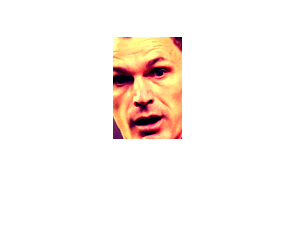

% main.mlx
% Facial Recognition System

%hyperparameters
% instruction: 
% L
%           length of the bit-encoding of a singl r/g/b color. Color
%           space:[2^{3 \times L}]
% process_type and proc:
%           id and str array of image preprocessing types.
% eps: 
%           float, threshold of recognition.
% strid_ratio: 
%           float.   :=\frac{stride step size}{frame size}; 
% frame_ratio: 
%           float.   :=\frac{image size}{frame_size}
% synchronize_train_test:
%           whethe to add the same preprocessing process to
%           train set so as to cancel distribution shift.
L=3;
process_type=4;
proc=["original","rotate 90 clockwise","stretch width two times", "adjust color"];
eps=0.41;
stride_ratio=2.1;
frame_ratio=1/25;       
synchronize_train_test=0;

%train
if synchronize_train_test==1

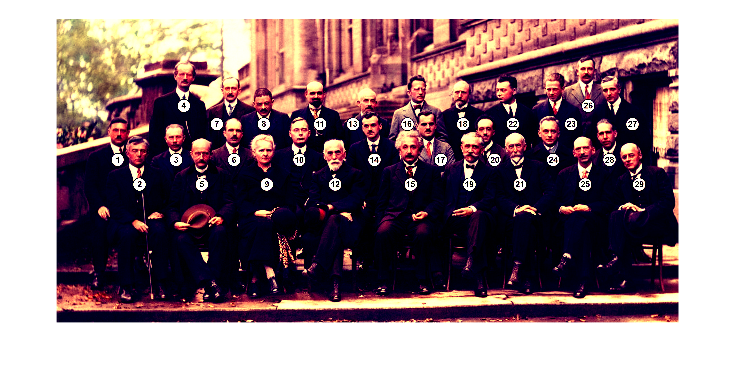

    v=train(L,"./Faces/",process_type);
else
    v=train(L,"./Faces/",0);
end

%preprocess test set.
im=prep("Solvay Conference.jpg",process_type);

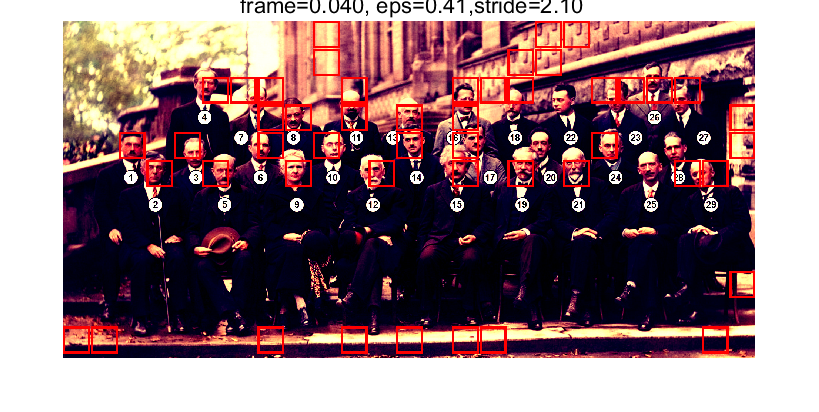

%test input image
im_proc=test(im,v,eps,L,stride_ratio,frame_ratio);

%visualize test result.
figure
imshow(im_proc);
title(sprintf("Solvay Conference Facial Recognition \n L=%d, pre-processing:" + ...
    " %s, \n frame=%1.3f, eps=%1.2f,stride=%1.2f",L,proc(process_type),frame_ratio,eps,stride_ratio));